# Data Analysis Wearable Robotics Project

## Import Data

fileToRead = "csvData/AD_Wearables/noWeight_1.csv";
MVCFile = "csvData/AD_Wearables/MVC_1.csv";

MVCFile = "csvData/AD_Wearables/MVC_1.csv"

D = readtable(fileToRead)

D = 68209×14 table
    EMG1TimeSeries_s_     EMG1_mV_     ACCXTimeSeries_s_    ACCX_G_    ACCYTimeSeries_s_    ACCY_G_     ACCZTimeSeries_s_    ACCZ_G_    GYROXTimeSeries_s_    GYROX_deg_s_    GYROYTimeSeries_s_    GYROY_deg_s_    GYROZTimeSeries_s_    GYROZ_deg_s_
    _________________    __________    _________________    _______    _________________    ________    _________________    _______    __________________    ____________    __________________    ____________    __________________    ____________

          

MVC = readtable(MVCFile)

MVC = 26072×14 table
    EMG1TimeSeries_s_     EMG1_mV_     ACCXTimeSeries_s_    ACCX_G_    ACCYTimeSeries_s_    ACCY_G_     ACCZTimeSeries_s_    ACCZ_G_    GYROXTimeSeries_s_    GYROX_deg_s_    GYROYTimeSeries_s_    GYROY_deg_s_    GYROZTimeSeries_s_    GYROZ_deg_s_
    _________________    __________    _________________    _______    _________________    ________    _________________    _______    __________________    ____________    __________________    ____________    __________________    ____________

        

## Process EMG Data

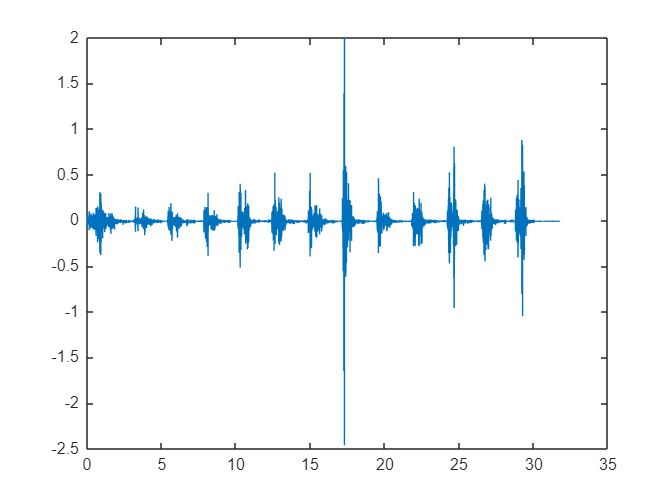

%Plot raw EMG data vs time
%We use the rmmissing function to remove NaN values from the raw data
EMGTime = rmmissing(D.EMG1TimeSeries_s_);
EMGRaw = rmmissing(D.EMG1_mV_);
figure 
plot(EMGTime, EMGRaw)

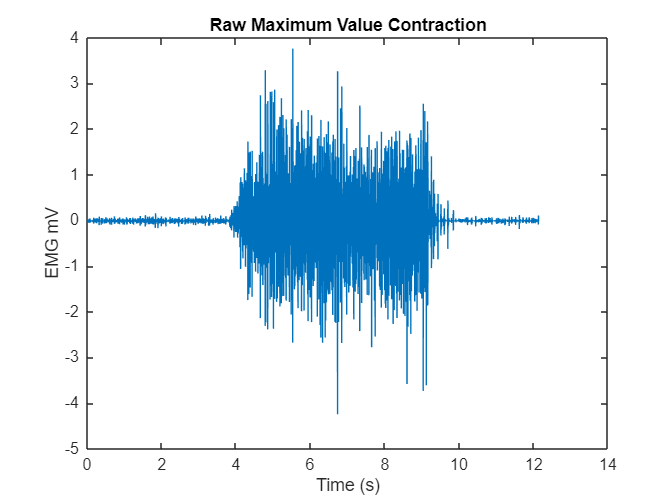

title("Raw EMG Data No Weight")
%Plot raw MVC vs time
figure
MVCEMGRaw = rmmissing(MVC.EMG1_mV_);
MVCEMGTime = rmmissing(MVC.EMG1TimeSeries_s_);
plot(MVCEMGTime, MVCEMGRaw)
title("Raw Maximum Value Contraction")
xlabel("Time (s)")
ylabel("EMG mV")

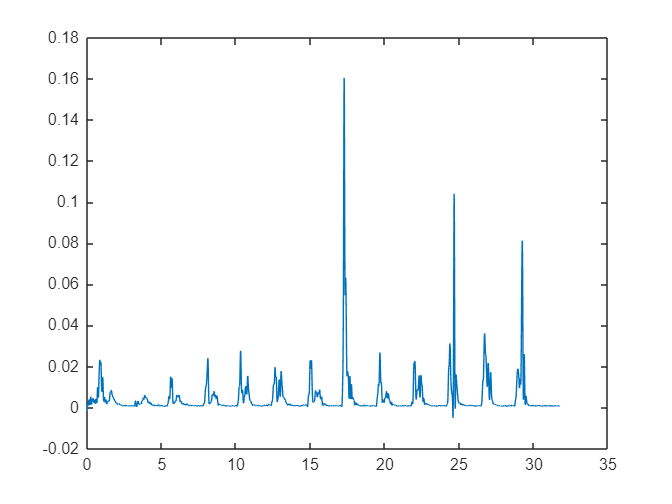

%Process and plot raw EMG data
EMGFreq = 1/(EMGTime(3) - EMGTime(2));
IMUFreq = 1/(D.ACCXTimeSeries_s_(3) - D.ACCXTimeSeries_s_(2));
processedEMG = ProcessEMG(EMGRaw, EMGFreq, IMUFreq);
IMUTime = rmmissing(D.ACCXTimeSeries_s_);
figure
plot(IMUTime, processedEMG)

title("Processed EMG Data")
xlabel("Time (s)")
ylabel("EMG mV")

## Process IMU Data (Get Orientations)

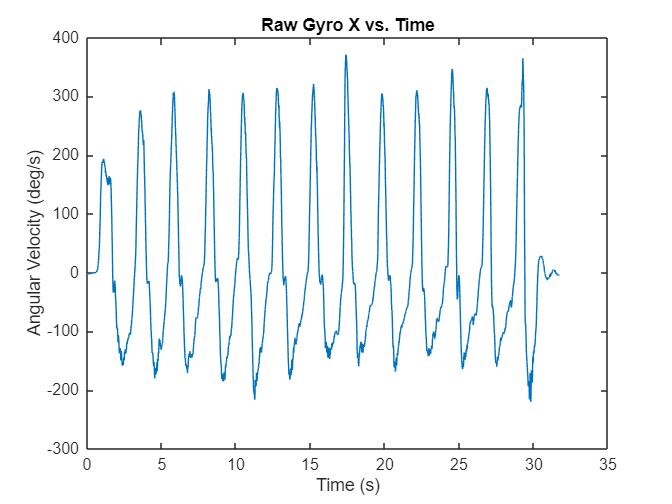

IMUGyroX = rmmissing(D.GYROX_deg_s_);
%Plot raw gyro vs. time
figure
plot(IMUTime, IMUGyroX)
title("Raw Gyro X vs. Time")
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")

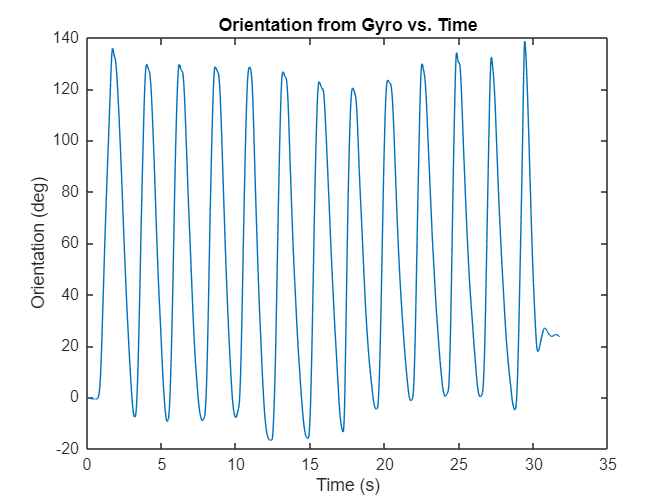

%Plot orientation vs time from Gyro integrals
orientationX = FindAngleFromGyro(IMUGyroX, IMUFreq);
figure
plot(IMUTime, orientationX)
title("Orientation from Gyro vs. Time")
xlabel("Time (s)")
ylabel("Orientation (deg)")

## Develop Joint Torque Estimate

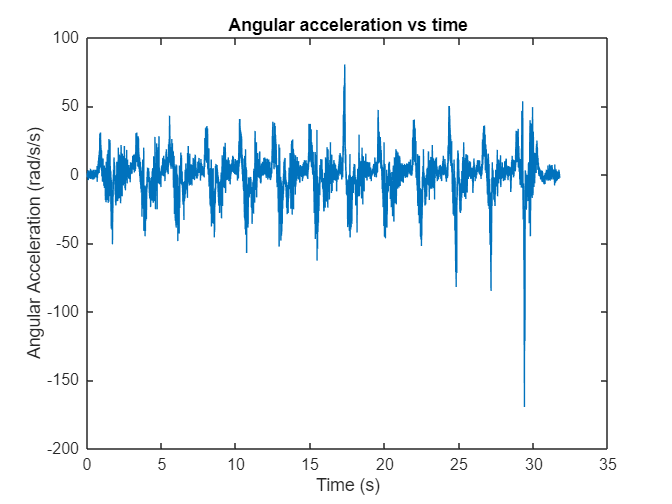

momentArm = 0.33; %Distance from AJ's elbow crease to ~middle of palm in meters
lowerArmMass = 2; %Mass of AJ's lower arm + hand in kg
lowerArmInertia = 1/12 * lowerArmMass * momentArm^2;
%Plot angular acceleration vs time
angAccelFromGyro = deg2rad(GetAngAccelFromGyro(IMUGyroX, IMUFreq));
figure
plot(IMUTime(1:length(angAccelFromGyro)), angAccelFromGyro)
title("Angular acceleration vs time")
xlabel("Time (s)")
ylabel("Angular Acceleration (rad/s/s)")

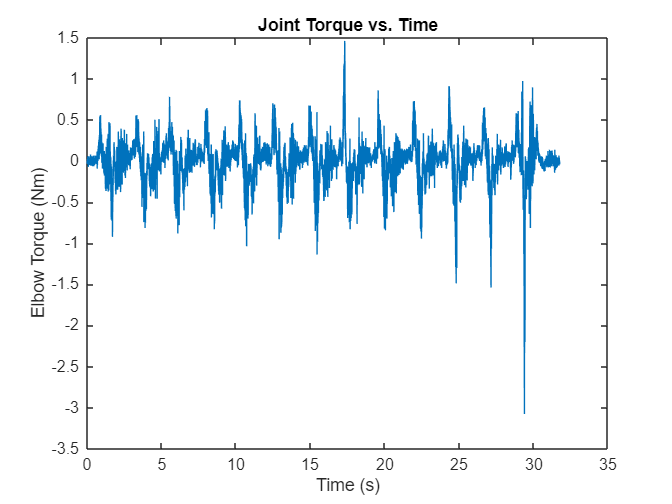

elbowTorque = lowerArmInertia .* angAccelFromGyro; %This is a rough joint torque estimate that does not 
%account for shoulder joint movement. I tried to keep my shoulder pretty still while recording the data though.
%Plot joint torque
plot(IMUTime(1:length(elbowTorque)), elbowTorque)
title("Joint Torque vs. Time")
xlabel("Time (s)")
ylabel("Elbow Torque (Nm)")